## Actividad 3 (Evaluación)

#### Pamela Hernández Montero A01736368

# Ejercicio 1.

Los ejes los posicioné de la siguiente manera, haciendo que concuerden las z de las juntas con el movimiento que realizan para el giro de la junta final se roto -90 grados en X por términos de practicidad.

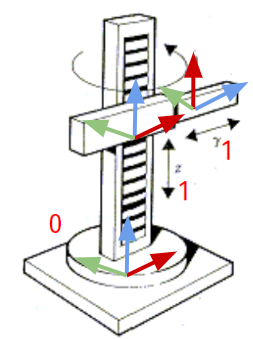

%Limpieza de pantalla
clear all
close all
clc

%Declaración de variables simbólicas (no tienen valor especifico)
syms th1(t) l1 %Primera junta
syms l2(t)  %Segunda junta
syms l3(t)  %Tercera junta
syms t
syms h

RP=[0 1 1]; %configuracion del robot, 0 para junta rotacional y 1 para prismatica 

% Vector de coordenadas articulares y generalizada
Q = [th1, l2(t), l3(t)];
disp('Coordenadas articulares y generalizadas:');pretty(Q);

Coordenadas articulares y generalizadas:
(th1(t), l2(t), l3(t))



%vector de velocidad articulares
Qp = diff(Q,t); %se utiliza diff para derivadas cuya variable no depende de otras
disp('Velocidades articulares'); pretty(Qp); 

Velocidades articulares
/  d          d         d       \
| -- th1(t), -- l2(t), -- l3(t) |
\ dt         dt        dt       /



%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

Análisis de articulaciones.

La primer articulación es una junta de movimiento rotacional que con respecto al marco de referencia tiene una altura h y que rota alrededor del eje  z 

%Articulacion 1 
%Posicion de la junta 1 respecto a 0
P(:,:,1) = [0;  0;  h];

% Definir la matriz de rotación
R(:,:,1) = [cos(th1) -sin(th1) 0; 
            sin(th1) cos(th1) 0; 
             0        0       1];

La segunda articulación es una junta prismática que cambia una altura l2 debido a que requiere ajustarse con la ultima junta rota en X -90 grados

%Articulación 2 
%Posición de la articulación 2 respecto a 1
P(:,:,2)= [0; 0 ; l2];

%Matriz de rotación de la junta 2 respecto a 3 (en x -90 grados)
R(:,:,2) = [1  0  0;
           0   0  1;
           0  -1  0];

Por último la tercera articulación es una junta prismática que no se modifica es por ello que tiene la matriz identidad, del mismo modo su posicion cambia con respecto a l3.

%Articulación 3 
%Posición de la articulación 3 respecto a 2
P(:,:,3)= [0; 0 ;l3];
%Matriz de rotación de la junta 3 respecto a 2   
R(:,:,3)= [1  0  0;
           0  1  0;
           0  0  1];

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);
%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 
for i= 1: GDL
    i_str = num2str(i);
    %locales
    disp(strcat('Matriz de transformacion local A',i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    pretty (A(:,:,i));

    %globales
    try 
        T(:,:,i) = T(:,:,i-1)*A(:,:,i);
    catch 
        T(:,:,i) = A(:,:,i); %caso especifico cuando i= 1 nos marcaria error en try
    end 
    disp(strcat('Matriz de transformacion global T',i_str));
    T(:,:,i) = simplify(T(:,:,i));
    pretty(T(:,:,i));

    %obtenemos la matriz de rotacion RO y el vector de translacion PO de la
    %matriz de transformacion homogenea global T(:,:,GDL)

    RO(:,:,i) = T(1:3,1:3,i);
    PO(:,:,i) = T(1:3,4,i);
    pretty(RO(:,:,i));
    pretty(PO(:,:,i));
end 

Matriz de transformacion local A1


/ cos(th1(t)), -sin(th1(t)), 0, 0 \
|                                 |
| sin(th1(t)),  cos(th1(t)), 0, 0 |
|                                 |
|      0,            0,      1, h |
|                                 |
\      0,            0,      0, 1 /



Matriz de transformacion global T1


/ cos(th1(t)), -sin(th1(t)), 0, 0 \
|                                 |
| sin(th1(t)),  cos(th1(t)), 0, 0 |
|                                 |
|      0,            0,      1, h |
|                                 |
\      0,            0,      0, 1 /



/ cos(th1(t)), -sin(th1(t)), 0 \
|                              |
| sin(th1(t)),  cos(th1(t)), 0 |
|                              |
\      0,            0,      1 /



/ 0 \
|   |
| 0 |
|   |
\ h /



Matriz de transformacion local A2


/ 1,  0, 0,   0   \
|                 |
| 0,  0, 1,   0   |
|                 |
| 0, -1, 0, l2(t) |
|                 |
\ 0,  0, 0,   1   /



Matriz de transformacion global T2


/ cos(th1(t)),  0, -sin(th1(t)),     0     \
|                                          |
| sin(th1(t)),  0,  cos(th1(t)),     0     |
|                                          |
|      0,      -1,       0,      h + l2(t) |
|                                          |
\      0,       0,       0,          1     /



/ cos(th1(t)),  0, -sin(th1(t)) \
|                               |
| sin(th1(t)),  0,  cos(th1(t)) |
|                               |
\      0,      -1,       0      /



/     0     \
|           |
|     0     |
|           |
\ h + l2(t) /



Matriz de transformacion local A3


/ 1, 0, 0,   0   \
|                |
| 0, 1, 0,   0   |
|                |
| 0, 0, 1, l3(t) |
|                |
\ 0, 0, 0,   1   /



Matriz de transformacion global T3


/ cos(th1(t)),  0, -sin(th1(t)), -sin(th1(t)) l3(t) \
|                                                   |
| sin(th1(t)),  0,  cos(th1(t)),  cos(th1(t)) l3(t) |
|                                                   |
|      0,      -1,       0,           h + l2(t)     |
|                                                   |
\      0,       0,       0,               1         /



/ cos(th1(t)),  0, -sin(th1(t)) \
|                               |
| sin(th1(t)),  0,  cos(th1(t)) |
|                               |
\      0,      -1,       0      /



/ -sin(th1(t)) l3(t) \
|                    |
|  cos(th1(t)) l3(t) |
|                    |
\      h + l2(t)     /



%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
V=simplify (Jv_a*Qp');
disp('Velocidad lineal obtenida mediante el Jacobiano lineal');pretty(V);

Velocidad lineal obtenida mediante el Jacobiano lineal
/   ________               _________                   \
|    d                      d                          |
| - -- l3(t) sin(th1(t)) - -- th1(t) cos(th1(t)) l3(t) |
|   dt                     dt                          |
|                                                      |
|  ________               _________                    |
|   d                      d                           |
|  -- l3(t) cos(th1(t)) - -- th1(t) sin(th1(t)) l3(t)  |
|  dt                     dt                           |
|                                                      |
|                       ________                       |
|                        d                             |
|                       -- l2(t)                       |
\                       dt                             /



W=simplify (Jw_a*Qp');
disp('Velocidad angular obtenido mediante el Jacobiano angular'); pretty(W);

Velocidad angular obtenido mediante el Jacobiano angular
/     0     \
|           |
|     0     |
|           |
| _________ |
|  d        |
| -- th1(t) |
\ dt        /



Conclusiones.

`La matriz de transformacion global T2 considera la altura h y l2(t) en su posicion debido a que depende de la junta 1 y 2. Por otro lado la matriz de transformacion global T3 depende del angulo de la junta rotacional 1 y de las alturas l2 y l3.`

`Las velocidades lineales de la junta prismatica 2 y 3 dependen entre si mientras y con respecto al angulo, mientras que las velocidades angulares son 0 en estas juntas debido a que no rotan al rededor de un eje. De otro modo la velocidad angular de la junta 1 es infinita.`

# Ejercicio 2.

Solo se analizaron para este ejercicio las juntas rotacionales

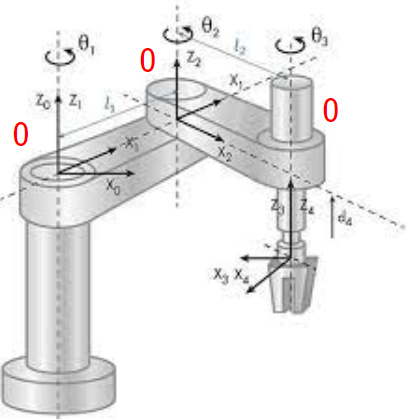

% Declaración de las variables simbólicas
syms q1(t) l1 q2(t) l2 q3(t) l3  h1 h2 h3
% Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP = [0 0 0];

% Vector de coordenadas articulares y generalizada
Q = [q1, q2, q3 ];
disp('Coordenadas articulares y generalizadas:');pretty(Q);

Coordenadas articulares y generalizadas:
(q1(t), q2(t), q3(t))




% Creamos el vector de velocidades articulares
Qp = diff(Q, t);
disp("Velocidades articulares "); pretty(Qp);

Velocidades articulares 
/  d         d         d       \
| -- q1(t), -- q2(t), -- q3(t) |
\ dt        dt        dt       /




% Número de grado de libertad del robot
GDL = size(RP, 2);
GDL_str = num2str(GDL);

Para la primera articulación, la posición se calcula considerando una altura fija h1, debido a que cada junta tiene una altura diferente se agrega en la posicion.

% Definición de la posición de las articulaciones con respecto a la
% anterior
P(:,:,1) = [l1*cos(q1); 
            l1*sin(q1);h1]; % Posición de la junta 1 respecto al origen
P(:,:,2) = [l2*cos(q2);
            l2*sin(q2);h2]; 
P(:,:,3) = [l3*cos(q3);
            l3*sin(q3);h3];
% Matriz de rotación de la articulaciones actuales con respecto a la
% anterior
R(:,:,1) = [cos(q1) -sin(q1) 0;
            sin(q1) cos(q1)  0;
            0          0     1];
R(:,:,2) = [cos(q2) -sin(q2) 0;
            sin(q2)  cos(q2) 0;
            0        0       1];
R(:,:,3) = [cos(q3) -sin(q3) 0;
            sin(q3)  cos(q3) 0;
            0        0       1];

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);
%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 
for i= 1: GDL
    i_str = num2str(i);
    %locales
    disp(strcat('Matriz de transformacion local A',i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    pretty (A(:,:,i));

    %globales
    try 
        T(:,:,i) = T(:,:,i-1)*A(:,:,i);
    catch 
        T(:,:,i) = A(:,:,i); %caso especifico cuando i= 1 nos marcaria error en try
    end 
    disp(strcat('Matriz de transformacion global T',i_str));
    T(:,:,i) = simplify(T(:,:,i));
    pretty(T(:,:,i));

    %obtenemos la matriz de rotacion RO y el vector de translacion PO de la
    %matriz de transformacion homogenea global T(:,:,GDL)

    RO(:,:,i) = T(1:3,1:3,i);
    PO(:,:,i) = T(1:3,4,i);
    pretty(RO(:,:,i));
    pretty(PO(:,:,i));
end 

Matriz de transformacion local A1


/ cos(q1(t)), -sin(q1(t)), 0, l1 cos(q1(t)) \
|                                           |
| sin(q1(t)),  cos(q1(t)), 0, l1 sin(q1(t)) |
|                                           |
|      0,          0,      1,       h1      |
|                                           |
\      0,          0,      0,       1       /



Matriz de transformacion global T1


/ cos(q1(t)), -sin(q1(t)), 0, l1 cos(q1(t)) \
|                                           |
| sin(q1(t)),  cos(q1(t)), 0, l1 sin(q1(t)) |
|                                           |
|      0,          0,      1,       h1      |
|                                           |
\      0,          0,      0,       1       /



/ cos(q1(t)), -sin(q1(t)), 0 \
|                            |
| sin(q1(t)),  cos(q1(t)), 0 |
|                            |
\      0,          0,      1 /



/ l1 cos(q1(t)) \
|               |
| l1 sin(q1(t)) |
|               |
\       h1      /



Matriz de transformacion local A2


/ cos(q2(t)), -sin(q2(t)), 0, l2 cos(q2(t)) \
|                                           |
| sin(q2(t)),  cos(q2(t)), 0, l2 sin(q2(t)) |
|                                           |
|      0,          0,      1,       h2      |
|                                           |
\      0,          0,      0,       1       /



Matriz de transformacion global T2


/ #2, -#1, 0, l1 cos(q1(t)) + l2 #2 \
|                                   |
| #1,  #2, 0, l1 sin(q1(t)) + l2 #1 |
|                                   |
|  0,  0,  1,        h1 + h2        |
|                                   |
\  0,  0,  0,           1           /

where

   #1 == sin(q1(t) + q2(t))

   #2 == cos(q1(t) + q2(t))




/ cos(q1(t) + q2(t)), -sin(q1(t) + q2(t)), 0 \
|                                            |
| sin(q1(t) + q2(t)),  cos(q1(t) + q2(t)), 0 |
|                                            |
\          0,                  0,          1 /



/ l1 cos(q1(t)) + l2 cos(q1(t) + q2(t)) \
|                                       |
| l1 sin(q1(t)) + l2 sin(q1(t) + q2(t)) |
|                                       |
\                h1 + h2                /



Matriz de transformacion local A3


/ cos(q3(t)), -sin(q3(t)), 0, l3 cos(q3(t)) \
|                                           |
| sin(q3(t)),  cos(q3(t)), 0, l3 sin(q3(t)) |
|                                           |
|      0,          0,      1,       h3      |
|                                           |
\      0,          0,      0,       1       /



Matriz de transformacion global T3


/ #2, -#1, 0, l1 cos(q1(t)) + l3 #2 + l2 cos(q1(t) + q2(t)) \
|                                                           |
| #1,  #2, 0, l1 sin(q1(t)) + l3 #1 + l2 sin(q1(t) + q2(t)) |
|                                                           |
|  0,  0,  1,                  h1 + h2 + h3                 |
|                                                           |
\  0,  0,  0,                       1                       /

where

   #1 == sin(q1(t) + q2(t) + q3(t))

   #2 == cos(q1(t) + q2(t) + q3(t))




/ cos(q1(t) + q2(t) + q3(t)), -sin(q1(t) + q2(t) + q3(t)), 0 \
|                                                            |
| sin(q1(t) + q2(t) + q3(t)),  cos(q1(t) + q2(t) + q3(t)), 0 |
|                                                            |
\              0,                          0,              1 /



/ l1 cos(q1(t)) + l3 cos(q1(t) + q2(t) + q3(t)) + l2 cos(q1(t) + q2(t)) \
|                                                                       |
| l1 sin(q1(t)) + l3 sin(q1(t) + q2(t) + q3(t)) + l2 sin(q1(t) + q2(t)) |
|                                                                       |
\                              h1 + h2 + h3                             /



%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
V=simplify (Jv_a*Qp');
disp('Velocidad lineal obtenida mediante el Jacobiano lineal');pretty(V);

Velocidad lineal obtenida mediante el Jacobiano lineal
/ - #4 (l3 sin(#1) + l2 sin(#2)) - #5 (l1 sin(q1(t)) + l3 sin(#1) + l2 sin(#2)) - l3 #3 sin(#1) \
|                                                                                               |
|  #4 (l3 cos(#1) + l2 cos(#2)) + #5 (l1 cos(q1(t)) + l3 cos(#1) + l2 cos(#2)) + l3 #3 cos(#1)  |
|                                                                                               |
\                                               0                                               /

where

   #1 == q1(t) + q2(t) + q3(t)

   #2 == q1(t) + q2(t)

         ________
          d
   #3 == -- q3(t)
         dt

         ________
          d
   #4 == -- q2(t)
         dt

         ________
          d
   #5 == -- q1(t)
         dt




W=simplify (Jw_a*Qp');
disp('Velocidad angular obtenido mediante el Jacobiano angular'); pretty(W);

Velocidad angular obtenido mediante el Jacobiano angular
/                0               \
|                                |
|                0               |
|                                |
| ________   ________   ________ |
|  d          d          d       |
| -- q1(t) + -- q2(t) + -- q3(t) |
\ dt         dt         dt       /



Conclusion:

Las velocidades lineales indican movimiento en los ejes x y y, mientras que el movimiento en el eje z se mantiene en cero, lo que implica que no hay velocidad lineal en la dirección z. Por otro lado, al examinar las velocidades angulares, se observa que no hay velocidad angular en los ejes x y y, pero sí en el eje z. Esta velocidad angular en el eje z es la suma de las derivadas respecto al tiempo de las posiciones angulares de las articulaciones en función del tiempo.